filepathData = 'data/raw/20220824/19-xyc-ex405nm_em415-10-735_S1-extrudate_GSH-CD_pH7_P1.nd2';
filepathBG = 'data/raw/20220824/0-xyc-dark.nd2';
filepathReferenceSpec = 'data/processed/Refspectra/Data4component.csv';

% load data
cl = CLSMspectraLab(filepathData);

Reading series #1
    ................................


clBin = cl.getBinnedObj(2);

cl.bgCorrection = bgCorrection.reference;
Iref = imageStack.import(filepathBG); % import background image

Reading series #1
    ................................


cl.bgCorrection(1).Iref = deal(Iref);
cl.bgCorrection(1).uniformBackgroundFlag = false;
cl = cl.computeBgCorrection;

Computed background correction using input image.


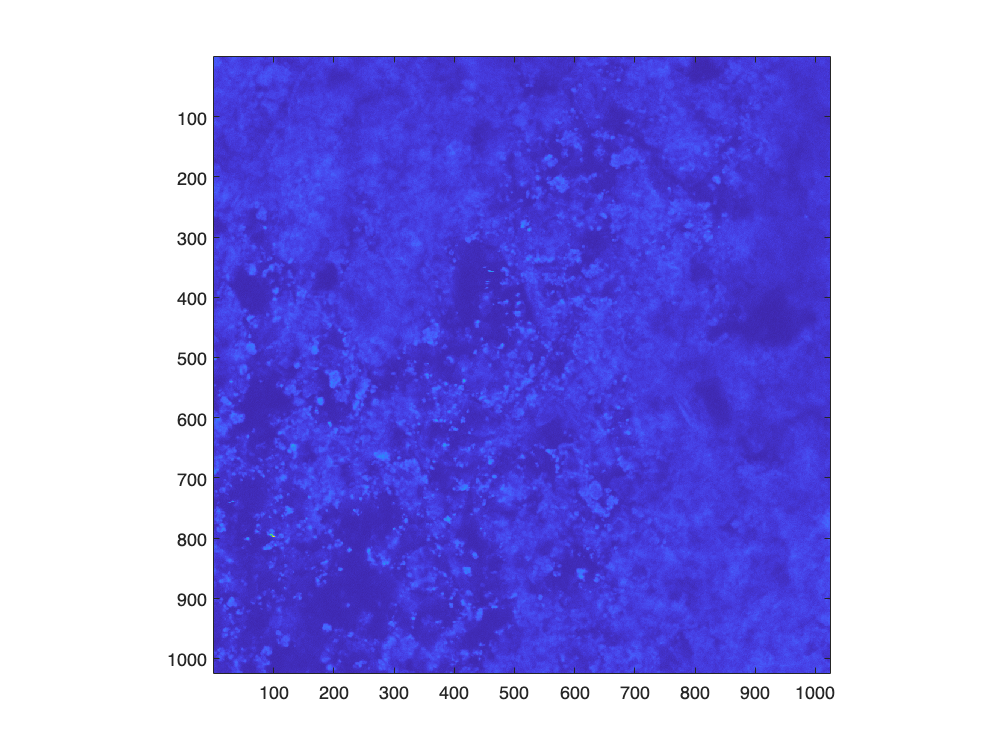

Plotting using background corrected image.


figure
cl.plotSumIntensity2D

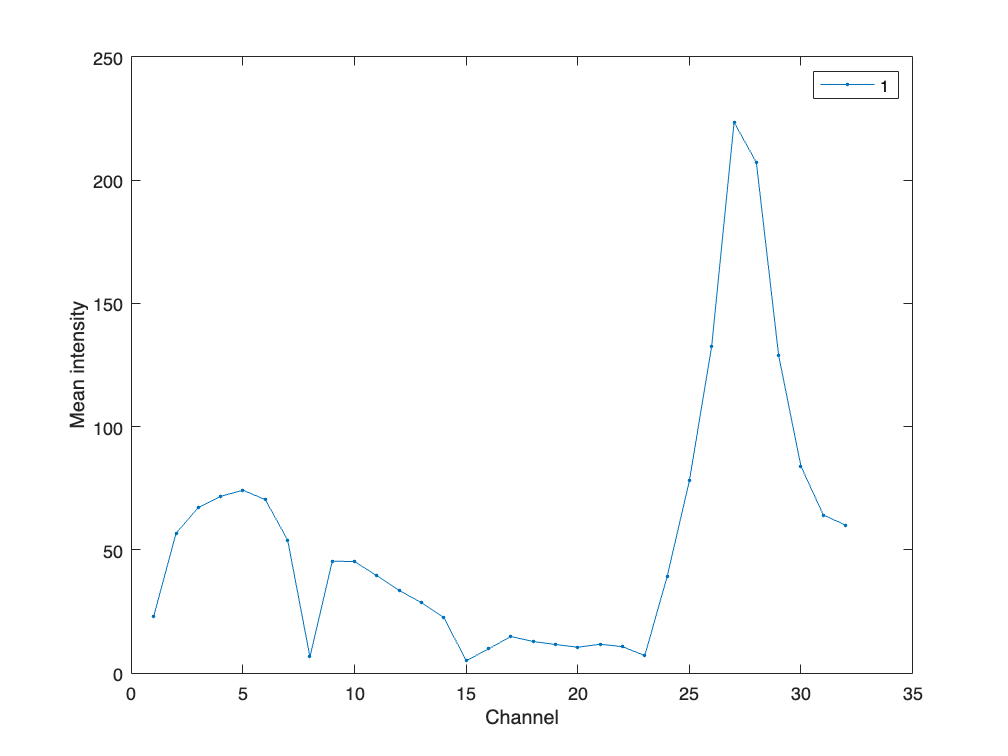

Plotting using background corrected image.


figure
cl.plotChannels

Plotting using background corrected image.


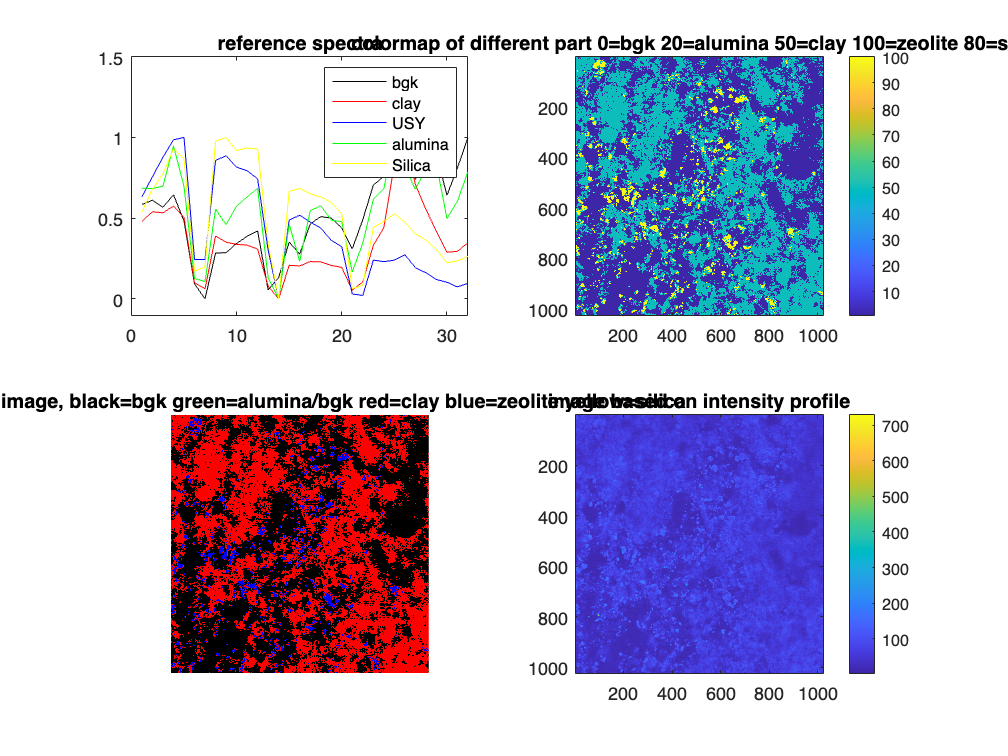

cl.resemblanceFit(1,0.07,0.03,filepathReferenceSpec)